# Low code time series and geospatial data handling, analysis and visualization

## Download data from Kaggle: [https://www.kaggle.com/datasets/decide-soluciones/air-quality-madrid](https://www.kaggle.com/datasets/decide-soluciones/air-quality-madrid)  

- madrid_2018.csv

- stations.csv

## Use the Import Data App to 

### import "madrid_2018.csv", then preview the File

madrid = importAirquality("madrid_2018.csv")

madrid = 69096×15 timetable
           date            BEN    CH4     CO     EBE    NMHC    NO    NO_2    NOx    O_3    PM10    PM25    SO_2    TCH     TOL     station  
    ___________________    ___    ____    ___    ___    ____    __    ____    ___    ___    ____    ____    ____    ____    ___    __________

    2018-03-01 01:00:00    NaN     NaN    0.3    NaN     NaN    1      29     31     NaN    NaN     NaN       2      NaN    Na


figure
scatter(madrid.NO,madrid.NOx)
xlabel("NO");
ylabel("NOx");
title("NOx vs NO");
legend("show");
set(gcf, "Theme", "light");
data1 = findobj(gcf,"DisplayName","data1")

data1 =   Scatter (data1) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [1 6 4 1 1 1 1 1 3 2 2 1 1 1 1 1 11 1 1 9 1 1 1 1 1 4 3 1 1 4 1 1 3 1 1 1 1 1 1 1 8 1 1 5 1 1 1 1 1 3 1 1 1 1 1 1 3 1 1 1 1 1 1 1 6 1 1 3 1 1 1 1 1 3 1 1 1 1 1 1 3 1 1 1 1 1 4 3 7 1 1 2 1 1 1 1 1 3 1 1 1 1 1 1 4 1 … ] (1×69096 double)
              YData: [31 49 47 37 29 29 27 39 47 29 34 29 33 32 41 27 58 17 51 71 31 25 31 25 25 32 29 19 16 26 13 32 39 13 26 23 14 23 28 18 38 12 28 37 22 22 15 22 21 20 12 10 13 14 13 15 31 7 16 13 10 17 16 15 22 11 12 19 8 14 8 14 … ] (1×69096 double)
           SizeData: 36
              CData: [0.0660 0.4430 0.7450]

  Show 

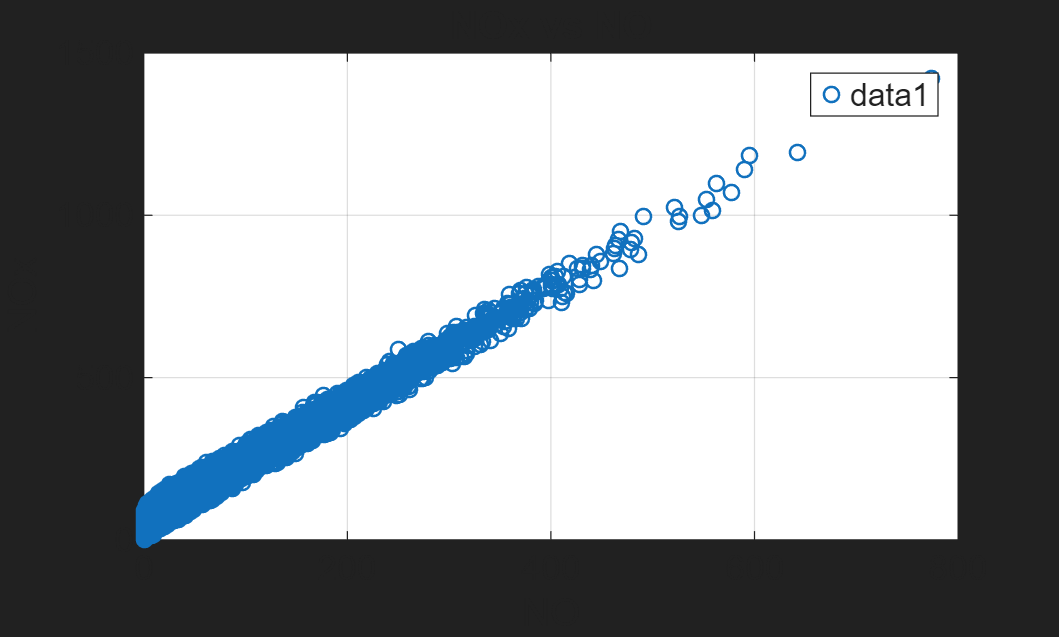

data1 =   Scatter (data1) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 1
              XData: [1 6 4 1 1 1 1 1 3 2 2 1 1 1 1 1 11 1 1 9 1 1 1 1 1 4 3 1 1 4 1 1 3 1 1 1 1 1 1 1 8 1 1 5 1 1 1 1 1 3 1 1 1 1 1 1 3 1 1 1 1 1 1 1 6 1 1 3 1 1 1 1 1 3 1 1 1 1 1 1 3 1 1 1 1 1 4 3 7 1 1 2 1 1 1 1 1 3 1 1 1 1 1 1 4 1 … ] (1×69096 double)
              YData: [31 49 47 37 29 29 27 39 47 29 34 29 33 32 41 27 58 17 51 71 31 25 31 25 25 32 29 19 16 26 13 32 39 13 26 23 14 23 28 18 38 12 28 37 22 22 15 22 21 20 12 10 13 14 13 15 31 7 16 13 10 17 16 15 22 11 12 19 8 14 8 14 … ] (1×69096 double)
           SizeData: 36
              CData: [0.0660 0.4430 0.7450]

  Show 

data1.LineWidth = 1

## Unstack Table Variable

## Clean Missing Data

## Check out the stations location

### import "stations.csv", then preview the File

Transform the "id" variable from *Double *to *String*

### Create a Plot - to plot the Stations on a map

## Change the geobasemap and fill the circles 

Ask [MATLAB GPT](https://chatgpt.com/g/g-QFTjbeK3U-matlab) or [MATLAB AI Chat Playground](https://uk.mathworks.com/matlabcentral/playground/new) to "change the format of degrees in the geographic plot"

(check the documentation!)

## Ask Copilot how to add station labels

"Can you add in the figure the text label (id) for the stations? Don't use a for loop"

`(Make sure "lat" is the first argument and "lon" the second one!!)`

Add a Colorbar (you can import a colormap from the IPCC [Standard-Climate-Colormaps-for-MATLAB - File Exchange - MATLAB Central](https://uk.mathworks.com/matlabcentral/fileexchange/180750-standard-climate-colormaps-for-matlab))

## BONUS! Launch and Explore the "signalAnalyzer" App

% NO_values = NO_new.("28079008");     % input data for signal analyzer

## You can now Try:

### Smooth Data

### Remove Trends, Outliers, etc

### Plot NO data at all stations in a single figure

asking copilot: *"NO_new variable has data from many stations (different columns). How can I plot all of them as tiles in a compiled figure?"*

Then open figure in window for better view

### Compare pollutant values

*e.g., NO with NO2 - unstack and clean missing values for NO2 and the plot NO vs NO2 and check out basic fitting*

Author: Kostas Leptokaropoulos

*Copyright 2025, The MathWorks, Inc.*